load plant_specs.mat

delta = 0.01;
x_min = 0;
x_max = dims.W;
x_vals = x_min:delta:x_max;

y_min = 0;
y_max = -dims.H;
y_vals = y_min:-delta:y_max;
[x_list, y_list] = meshgrid(x_vals,y_vals);
p_grid = cat(3,x_list, y_list);

[l,x,f, exitflags] = invKine(p_grid,invKineSys);

## Filters

%% Torque Safety Factor Filters
T = funcs.pulleyTorque(max(f.F21,f.F22));

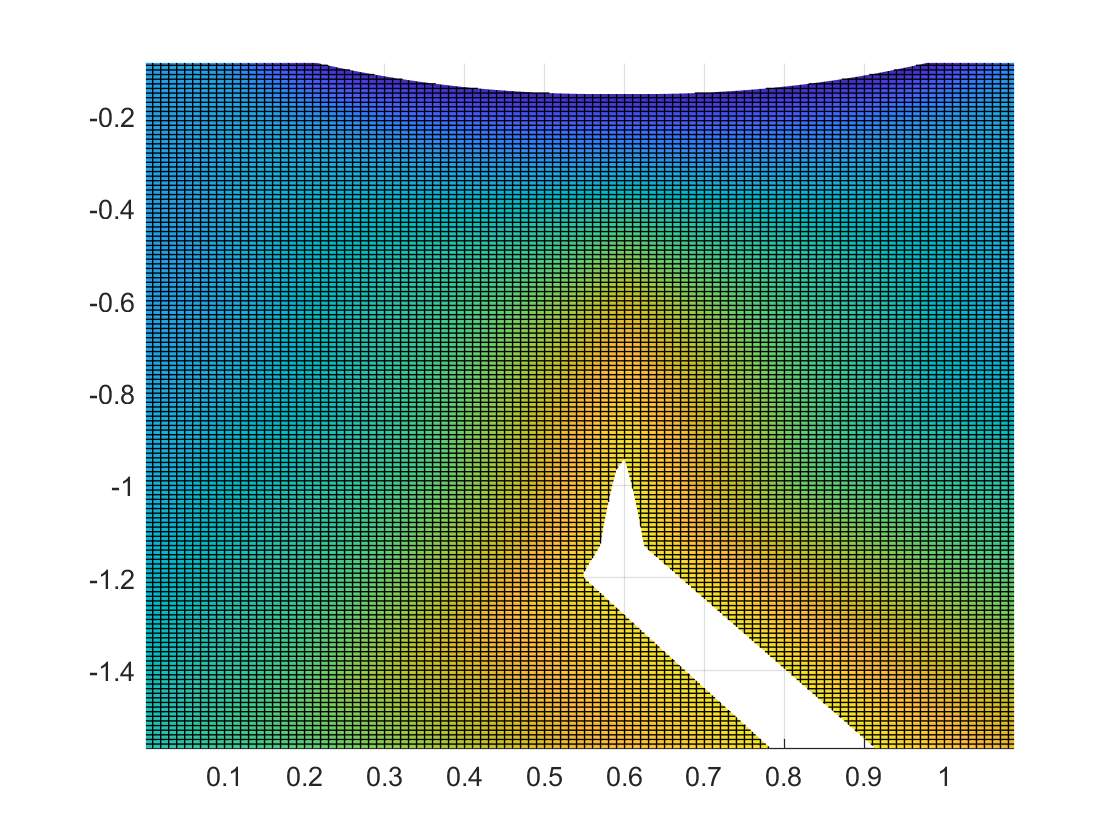

minTorqueSF = 2;
torqueSafetyFactor = motor.max_holding_torque./T;
masked_TSF = torqueSafetyFactor;
masked_TSF(masked_TSF<minTorqueSF) = NaN;
bin_TSF = torqueSafetyFactor;
bin_TSF(bin_TSF<minTorqueSF) = 0;
bin_TSF(isnan(bin_TSF)) = 0;
bin_TSF(bin_TSF>=minTorqueSF) = 1;
surf(x_list,y_list, masked_TSF)
axis([x_min x_max y_max y_min])

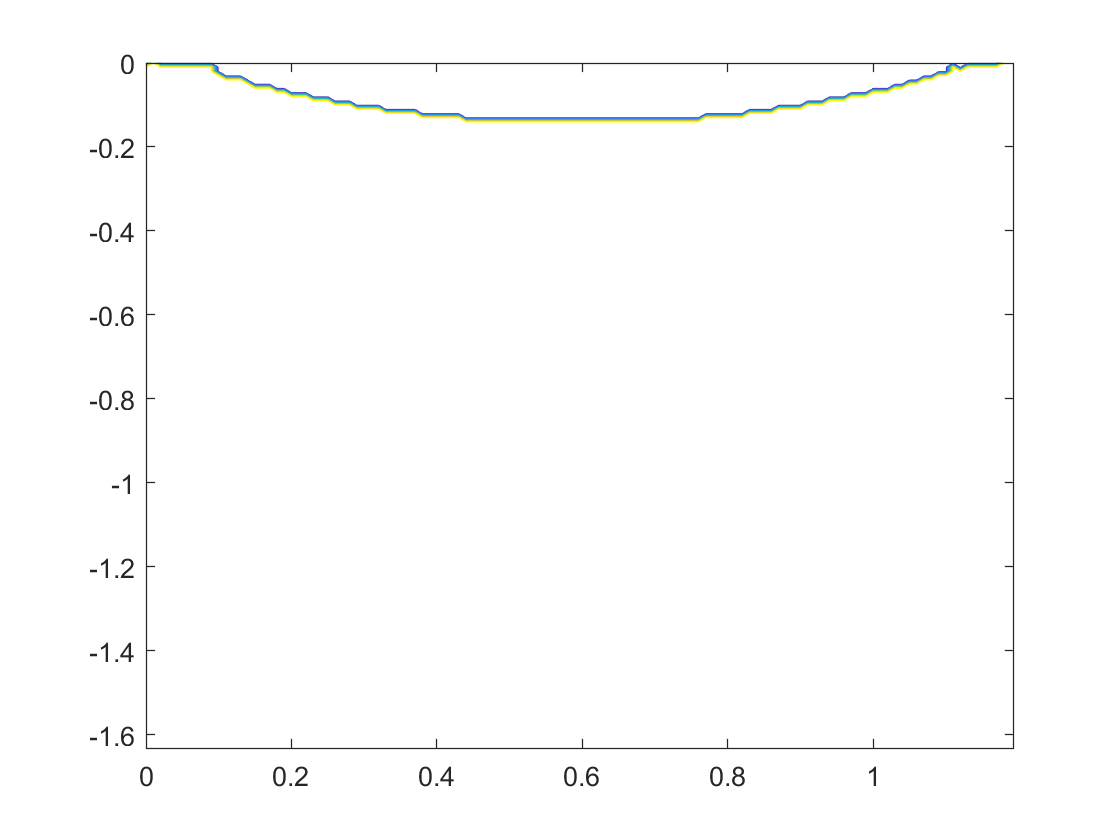


contour(x_list,y_list,bin_TSF)
axis([x_min x_max y_max y_min])

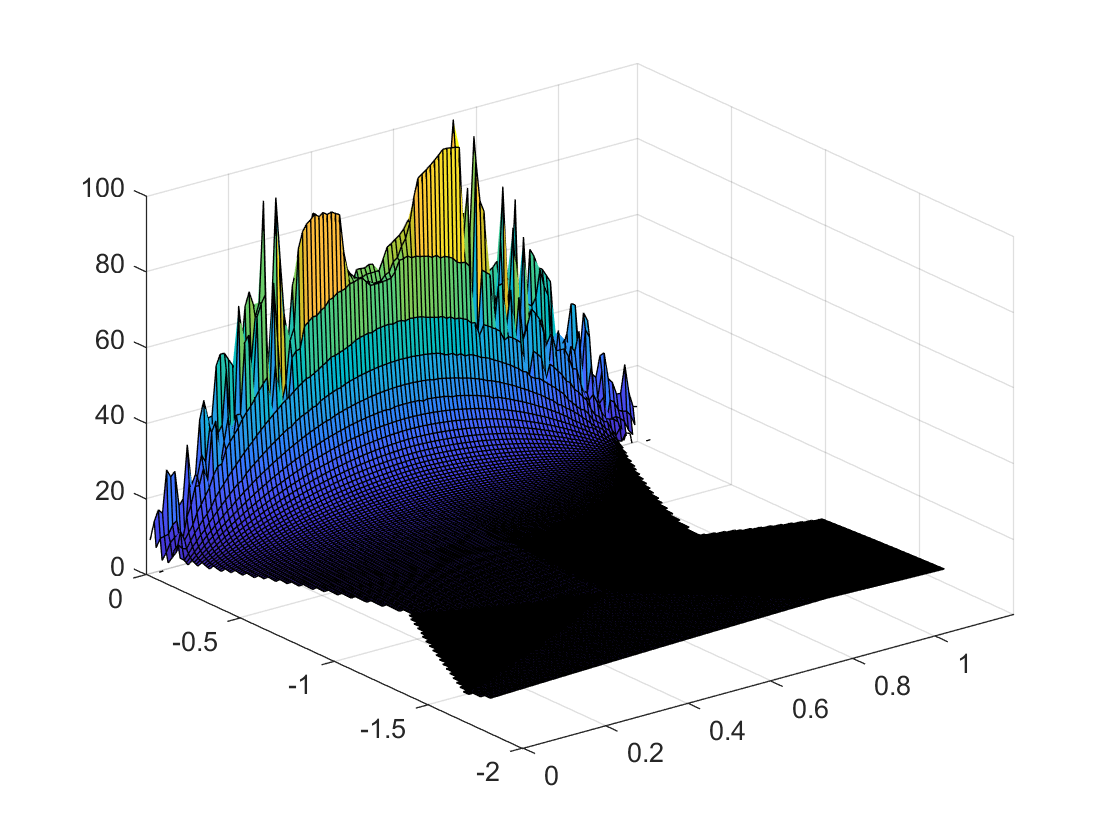

%% Min Line Tension Filters
minLineTension = 2;
lineTension = min(f.F21, f.F22);
masked_lineTension = lineTension;
masked_lineTension(masked_lineTension<minLineTension) = NaN;
surf(x_list, y_list, masked_lineTension)

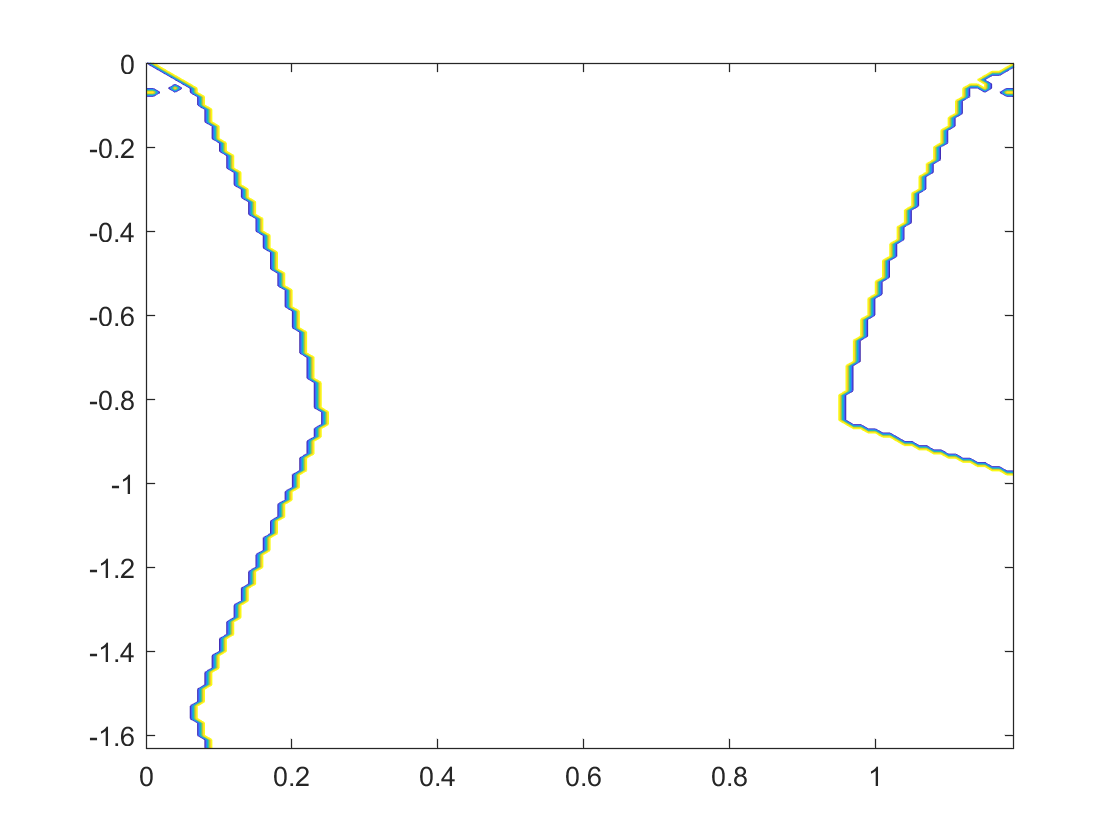

bin_LineTension = lineTension;
bin_LineTension(bin_LineTension<minLineTension) = 0;
bin_LineTension(isnan(bin_LineTension)) = 0;
bin_LineTension(bin_LineTension>=minLineTension) = 1;
contour(x_list,y_list,bin_LineTension)

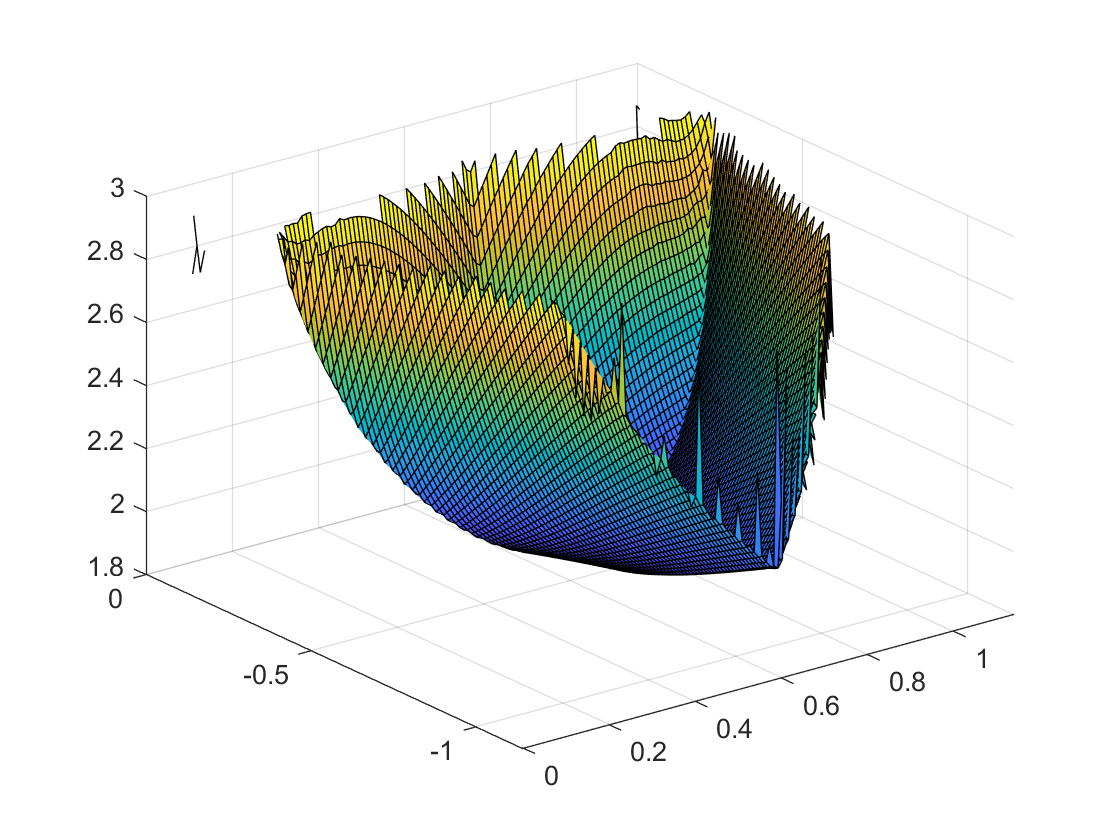

%Resolution (delta_p/delta_l) Filter
%Redo This with Forward Kinematics or Think More; Do with simple direct
%equations as a check
max_allowable_dpdl = 3; %Max 5 change in point to 1 change in line
[dl1dx, dl1dy] = gradient(l.l1, delta);
dpdl1 = vecnorm(cat(3,1./dl1dx, 1./dl1dy),2,3);
masked_dpdl1 = dpdl1;
masked_dpdl1(masked_dpdl1>max_allowable_dpdl) = NaN;
[dl2dx, dl2dy] = gradient(l.l2, delta);
dpdl2 = vecnorm(cat(3,1./dl2dx, 1./dl2dy),2,3);
masked_dpdl2 = dpdl2;
masked_dpdl2(masked_dpdl2>max_allowable_dpdl) = NaN;
max_dpdl = max(dpdl1, dpdl2);
masked_max_dpdl = max_dpdl;
masked_max_dpdl(masked_max_dpdl>max_allowable_dpdl) = NaN;
surf(x_list, y_list, masked_max_dpdl)

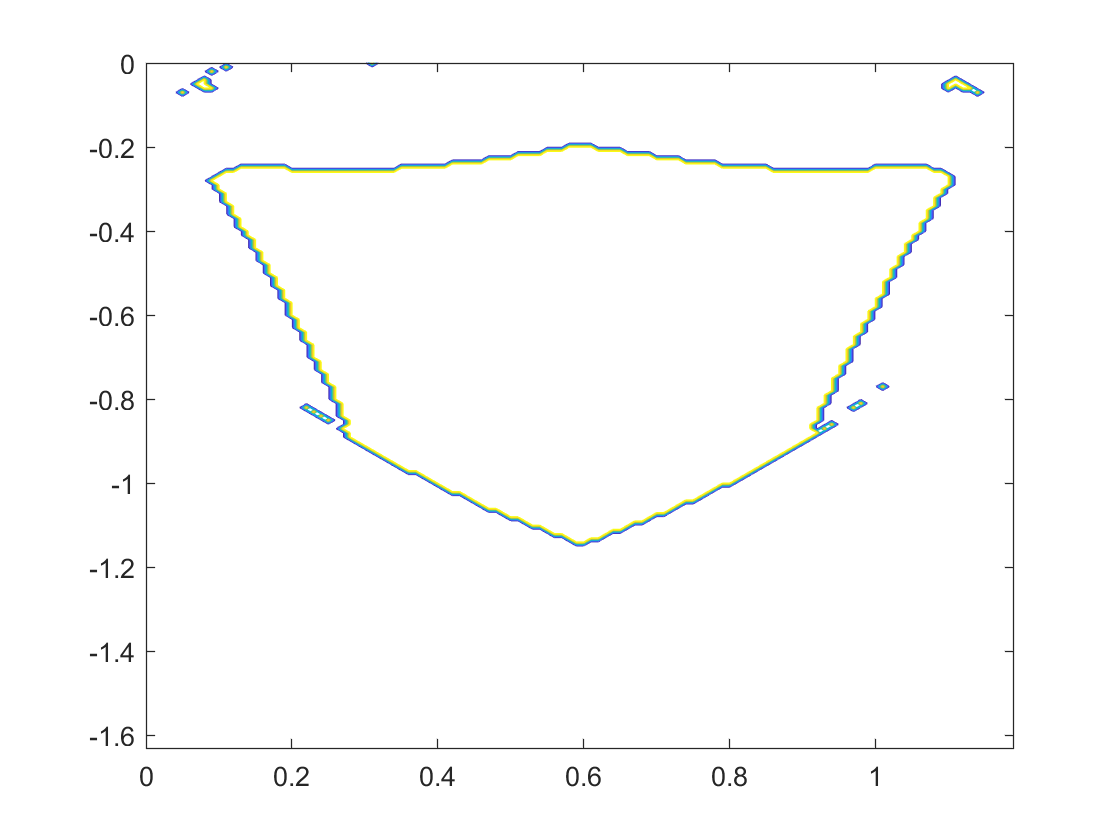

bin_max_dpdl = max_dpdl;
bin_max_dpdl(bin_max_dpdl<=max_allowable_dpdl) = 1;
bin_max_dpdl(bin_max_dpdl>max_allowable_dpdl) = 0;
bin_max_dpdl(isnan(bin_max_dpdl)) = 0;

contour(x_list,y_list,bin_max_dpdl)

## Combine Results

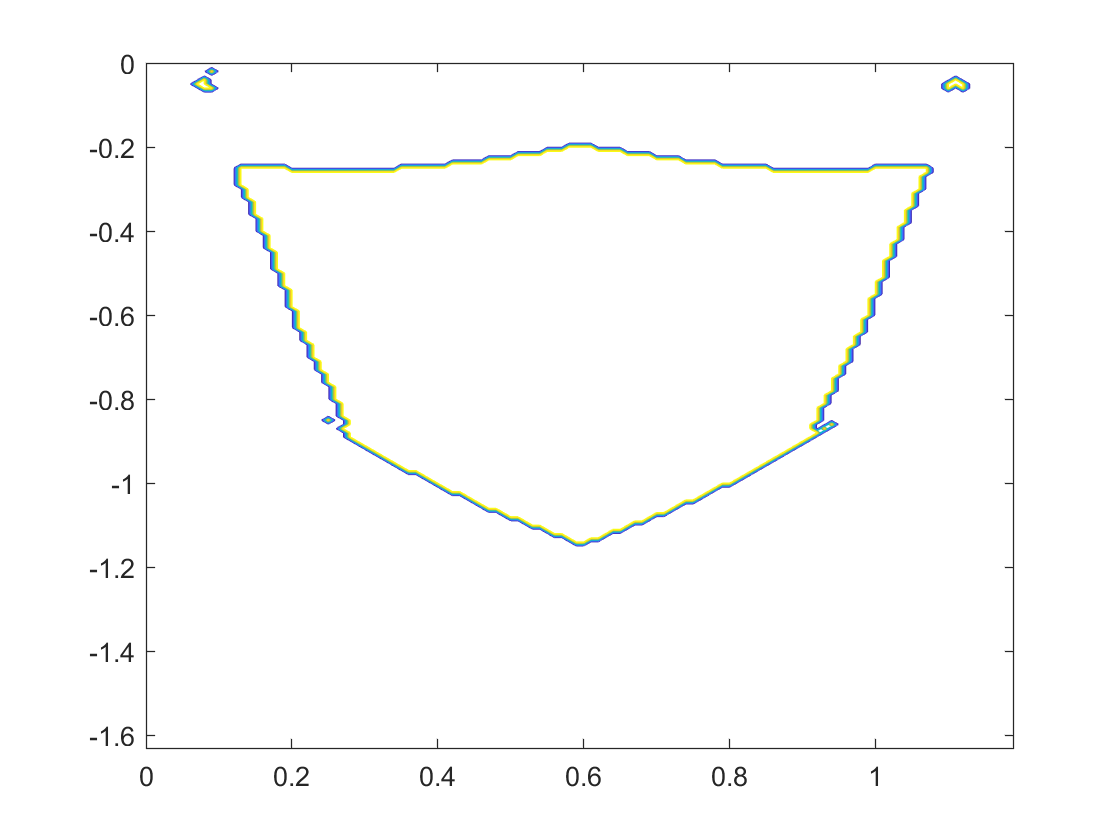

bin_boundary = bin_TSF & bin_LineTension & bin_max_dpdl;
contour(x_list, y_list, bin_boundary)

save("boundaryResults.mat", "l","x", "f", "T", "exitflags");